## Relatório Projeto 2 - Matemática Computacional

### 1

### a) e b)

format Long
t = [1 2 5 7 8 9 12]

t =      1     2     5     7     8     9    12


ft = [0.9 0.4 0.18 0.2 0.22 0.27 0.36]

ft =    0.900000000000000   0.400000000000000   0.180000000000000   0.200000000000000   0.220000000000000   0.270000000000000   0.360000000000000


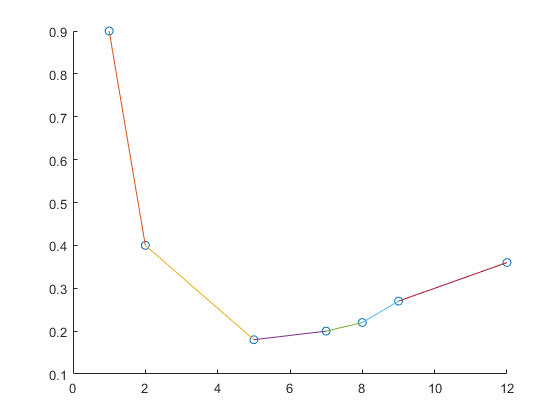

splinelinear(t,ft)

### c)

getvalue(t,ft,3)

ans =    0.340000000000000


A fórmula de erro para

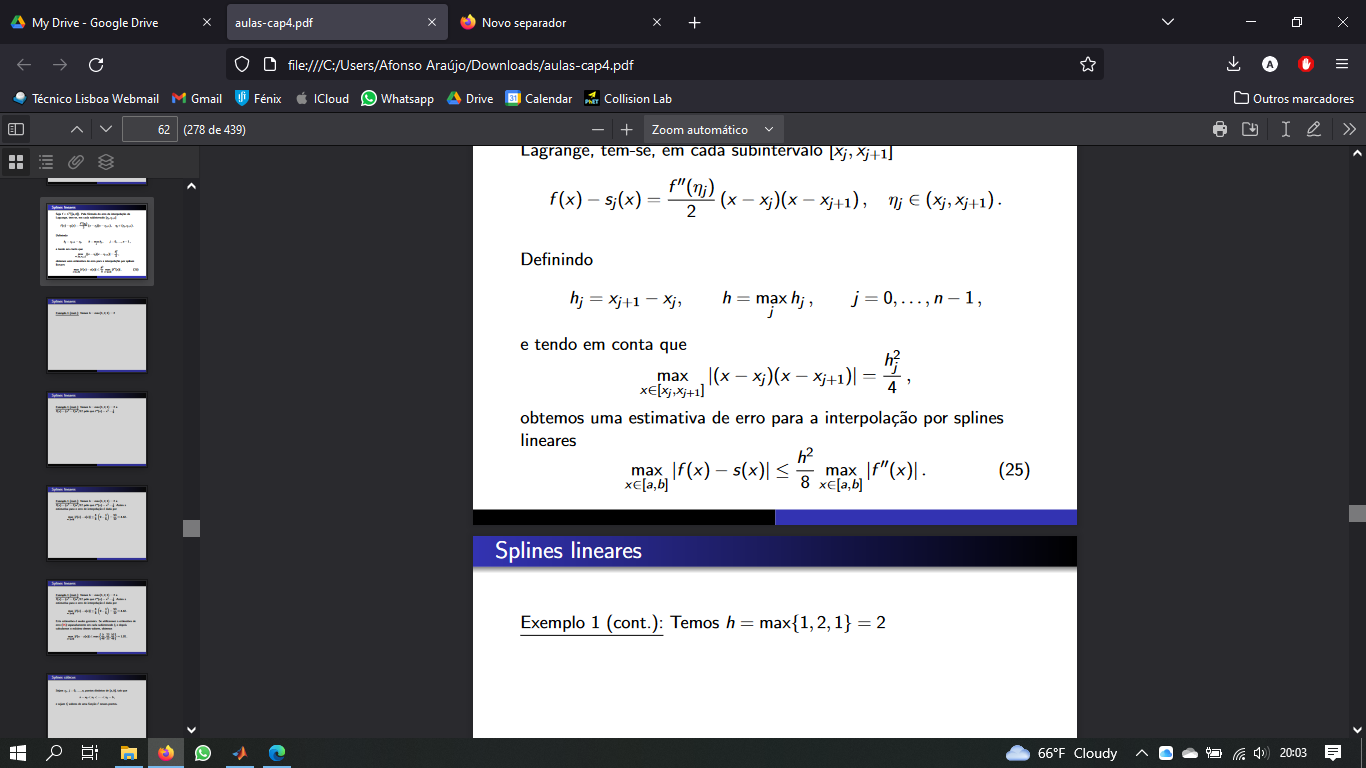

 0<f''(x)<1

calculamos os h para saber qual o máximo

%Descobrir o h máximo
n = numel(t)

n =      7


hmax = 0;
for i = 1:1:n-1
    if t(i+1)-t(i) > hmax
        hmax = t(i+1)-t(i);
    end
end

Considerando o pior dos casos para a 2 derivada de f no intervalo [1,12] podemos majorar o erro da seguinte forma:

M = ((hmax.^2)./8).*(1)

M =    1.125000000000000


Ainda assim este erro é muito grosseiro. Ao utilizar a fórmula de erro para cada subintervalo temos no ponto t=3:

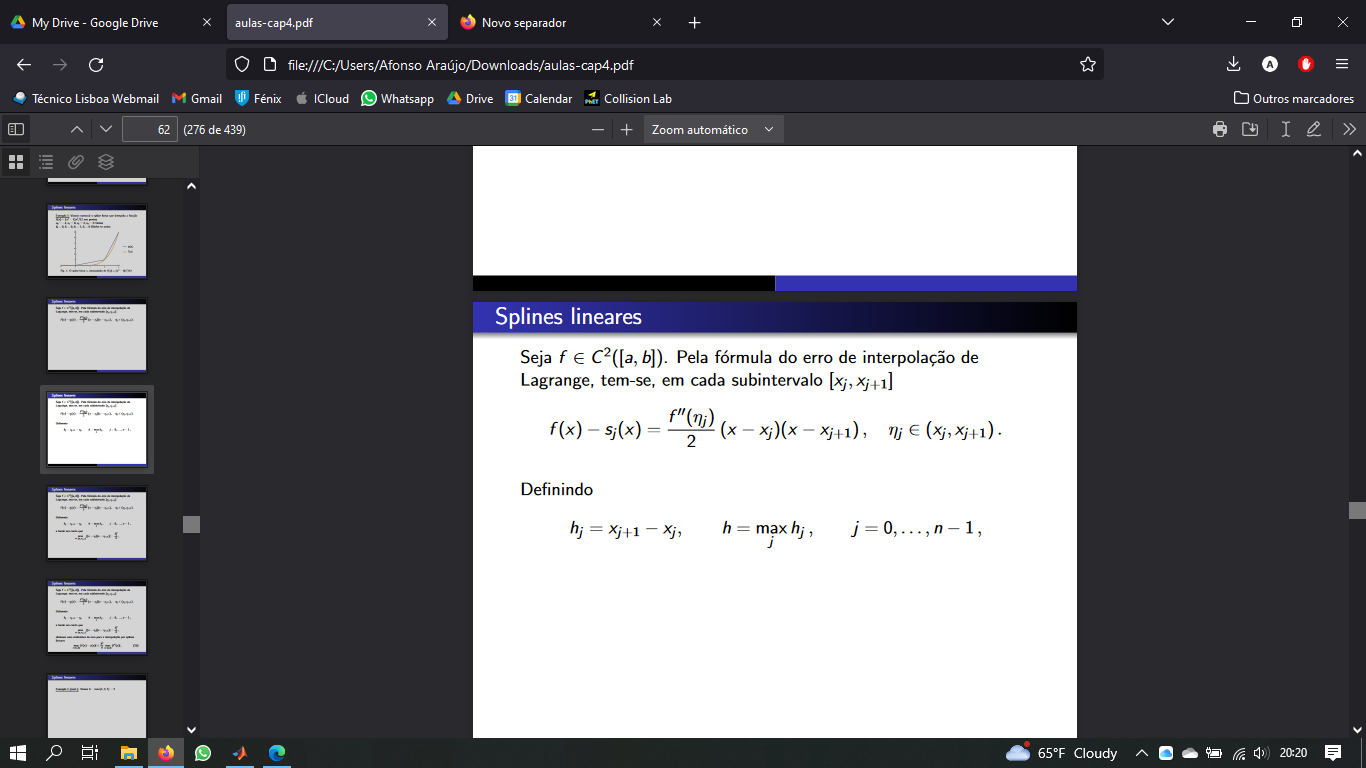

N = (1./2).*(3-2).*(3-5)

N =     -1


**Esta fórmula serve para aqui???**

### d)

Definem-se as funções de base

phi0 = @(t) exp(-3.*t)

phi0 = function_handle with value:
    @(t)exp(-3.*t)


phi1 = @(t) exp(0.1.*t)

phi1 = function_handle with value:
    @(t)exp(0.1.*t)


phi2 = @(t) exp(-t)

phi2 = function_handle with value:
    @(t)exp(-t)



coef = minq3(t,ft,phi0,phi1,phi2)

coef =    1.078218315985077
   0.104905974210165
   1.985444480853854



f = @(t) coef(1).*phi0(t) + coef(2).*phi1(t) + coef(3).*phi2(t)

f = function_handle with value:
    @(t)coef(1).*phi0(t)+coef(2).*phi1(t)+coef(3).*phi2(t)


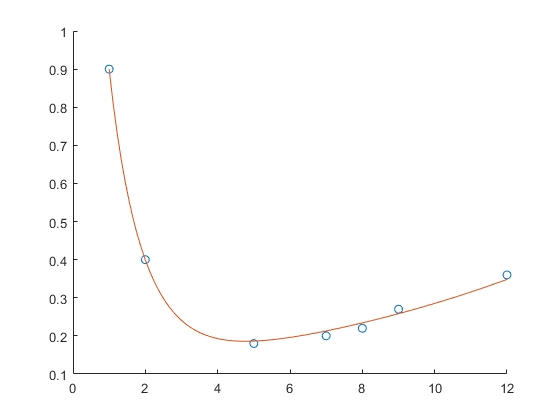


scatter(t,ft)
hold on
x = linspace(1,12,100);
plot(x,f(x))
hold off

### 2.

### a)

format long
volexact = 3.198423723387142

volexact =    3.198423723387142


g = @(x) pi.*(exp(-cos(x))).^2;
a = 1;
b = 2;

%Cálculo dos integrais para diferentes números de subintervalos
h = [];
v = [];
e = [];
ns = 10:10:100;
for i = 1:1:numel(ns)
    [v(i),h(i)] = Trapcomp(g,a,b,ns(i));
    e(i) = abs(v(i)-volexact);
end

%Representação gráfica do resultado linearizado
R = [ns' h' e'];
Rlin = [ns' log(h)' log(e)'];
scatter(Rlin(:,2), Rlin(:,3))
hold on

%Aproximação com mínimos quadrados
phi4 = @(t) (t == 0) .* 1 + (t ~= 0) .* 1;
phi5 = @(t) t;
coef = minq2(Rlin(:,2),Rlin(:,3),phi4,phi5)

coef =   -0.056484191461176
   2.000060287256971


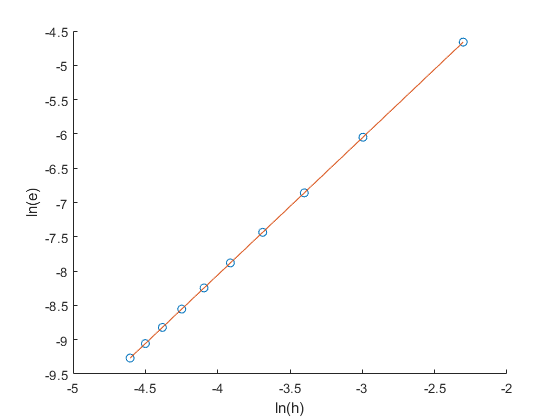

fminq = @(x) coef(1) + coef(2).*x;

%Gráfico da reta de aproximação
x = linspace(Rlin(1,2),Rlin(end,2),100);
plot(x, fminq(x))
xlabel('ln(h)')
ylabel('ln(e)')
hold off

p = 2 justificar que é o coeficiente 

### b)

format long
volexact = 3.198423723387142

volexact =    3.198423723387142


g = @(x) pi.*(exp(-cos(x))).^2;
a = 1;
b = 2;

%Cálculo dos integrais para diferentes números de subintervalos
h = [];
v = [];
e = [];
ns = 10:10:100;
for i = 1:1:numel(ns)
    [v(i),h(i)] = Simpcomp(g,a,b,ns(i));
    e(i) = abs(v(i)-volexact);
end

%Representação gráfica do resultado linearizado
R = [ns' h' e'];
Rlin = [ns' log(h)' log(e)'];
scatter(Rlin(:,2), Rlin(:,3))
hold on

%Aproximação com mínimos quadrados
phi4 = @(t) (t == 0) .* 1 + (t ~= 0) .* 1;
phi5 = @(t) t;
coef = minq2(Rlin(:,2),Rlin(:,3),phi4,phi5)

coef =   -2.800377594103114
   3.986341214944837


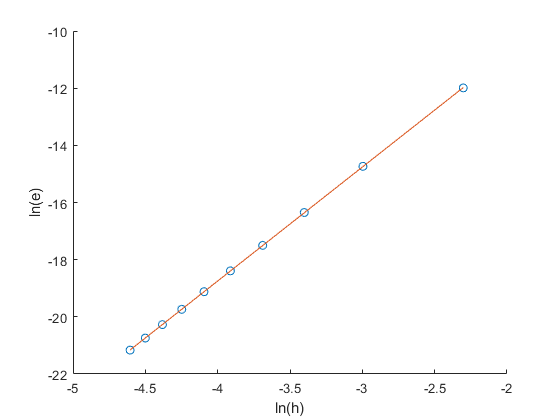

fminq = @(x) coef(1) + coef(2).*x;

%Gráfico da reta de aproximação
x = linspace(Rlin(1,2),Rlin(end,2),100);
plot(x, fminq(x))
xlabel('ln(h)')
ylabel('ln(e)')
hold off

p =~ 4 justificar a diferença dos ps nos diferentes métodos

### c)

Queremos Erro de V < 10e-7

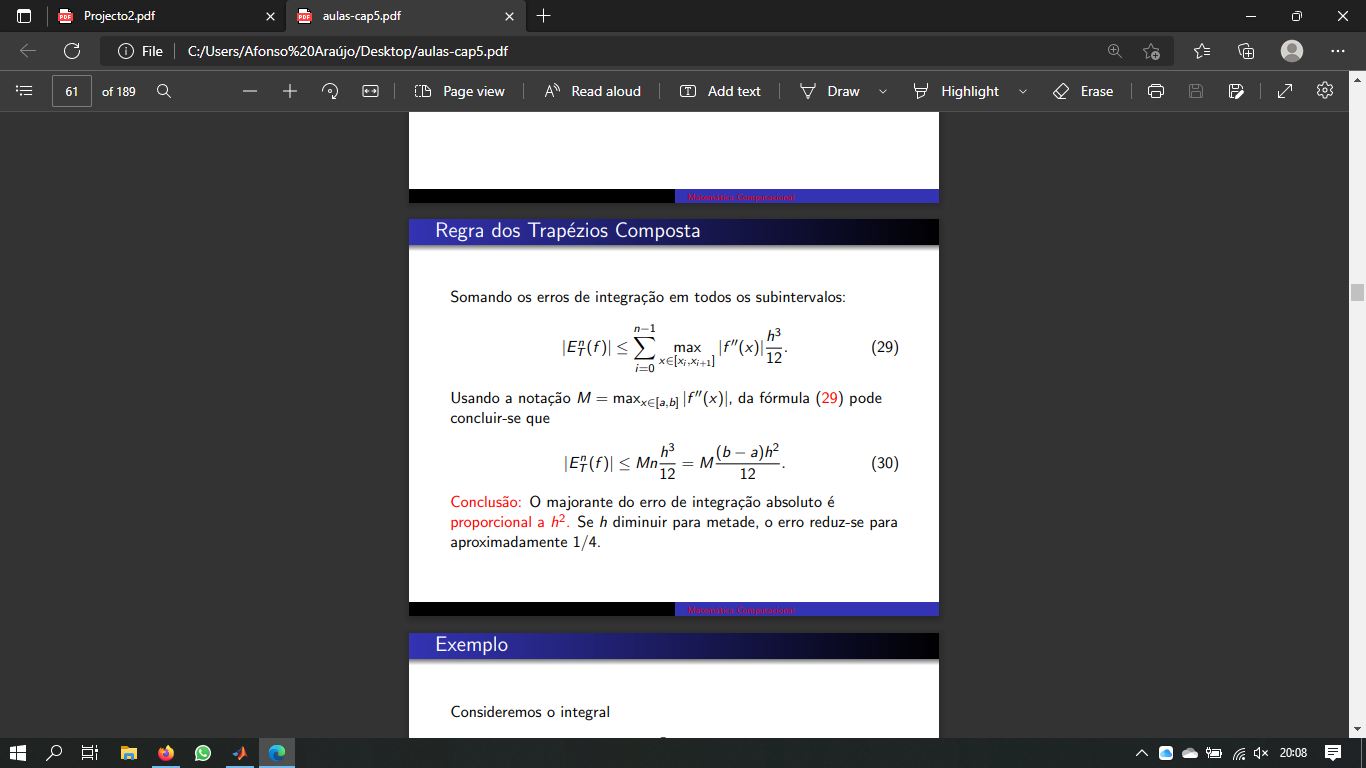

a=1;
b=2;
E = 10e-7;

M = máximo de f'' no intervalo [a,b]

g = @(x) pi.*(exp(-cos(x))).^2;
d1g = @(x) pi.*(exp(-2.*cos(x))).*2.*sin(x);
d2g = @(x) 2.*pi.*(2.*exp(-2.*cos(x)).*sin(x).^2+exp(-2.*cos(x)).*cos(x));
d3g = @(x) 2.*pi.*(4.*exp(-2.*cos(x)).*sin(x).^2+3.*exp(-2.*cos(x)).*sin(2.*x)-exp(-2.*cos(x)).*sin(x));

Falta mostrar que a 3 derivada é positiva e por isso o máximo etc...

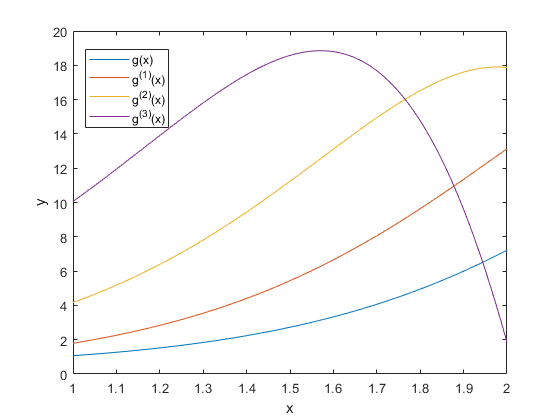

x = linspace(a,b,100);
plot(x,g(x))
hold on
plot(x,d1g(x))
plot(x,d2g(x))
plot(x,d3g(x))
legend({'g(x)','g^{(1)}(x)','g^{(2)}(x)','g^{(3)}(x)'},'Location','best')
xlabel('x')
ylabel('y')
hold off


M = d2g(b)

M =   17.872466717324365



%E = (M*(b-a)*h^2)/12 escrever latex
%rearanjado
h = sqrt(12*E/(M*(b-a)));
N = (b-a)/h;
ceil(N)

ans =         1221


Para verificar

[vol,h] = Trapcomp(g,a,b,1221);
erro = abs(volexact-vol)

erro =      6.337626694552512e-07


erro<=E

ans = logical
   1


Se fossem menos

[vol,h] = Trapcomp(g,a,b,900);
erro = abs(volexact-vol)

erro =      1.166468380997543e-06


erro<=E

ans = logical
   0


Podemos mostrar numa tabela qual seria o mínimo experimentalmente porque o stor das praticas disse que nao se usava teoria em trabalhos computacionais.

Uma tabela com os valores e dados logical a dizer se verifica ou não.

Para os pontos de interesse, sabemos que por volta de 1000 é o ponto de viragem

%pontos de interesse
format longG
vol = [];
erro = [];
logic = [];
i = 1;
for n = 100:100:1200
    [vol(i),~] = Trapcomp(g,a,b,n);
    erro(i) = abs(volexact-vol(i));
    logic(i) = erro(i)<=E;
    i = i+1;
end
n = 100:100:1200;
R = [n' vol' erro' logic']

R =                        100          3.19851820748526      9.44840981187411e-05                         0
                       200          3.19844734438148      2.36209943342836e-05                         0
                       300          3.19843422160436      1.04982172155488e-05                         0
                       400          3.19842962863384       5.9052466929721e-06                         0
                       500          3.19842750274488      3.77935773698823e-06                         0
                       600          3.19842634794107      2.62455392663341e-06                         0
                       700          3.19842565163082      1.92824367761801e-06                         0
                       800           3.1984251996987      1.47631155433814e-06                         0
                       900          3.19842488985552      1.16646838099754e-06                         0
                      1000          3.1984246682265

No intuito de refinar a pesquisa podemos fazer o mesmo para uns pontos mais próximos da solução:

%pontos de interesse
vol = [];
erro = [];
logic = [];
i = 1;
for n = 900:10:1000
    [vol(i),~] = Trapcomp(g,a,b,n);
    erro(i) = abs(volexact-vol(i));
    logic(i) = erro(i)<=E;
    i = i+1;
end
n = 900:10:1000;
R = [n' vol' erro' logic']

R =                        900          3.19842488985552      1.16646838099754e-06                         0
                       910          3.19842486435972      1.14097257331025e-06                         0
                       920          3.19842483969077      1.11630362420456e-06                         0
                       930           3.1984248158133      1.09242616019856e-06                         0
                       940          3.19842479269382      1.06930667920224e-06                         0
                       950          3.19842477030059      1.04691344882113e-06                         0
                       960          3.19842474860349      1.02521634470776e-06                         0
                       970          3.19842472757397      1.00418682391634e-06                         0
                       980          3.19842470718492      9.83797777021067e-07                         1
                       990          3.1984246874105

Pesquisa mais refinada:

%pontos de interesse
vol = [];
erro = [];
logic = [];
i = 1;
for n = 970:1:980
    [vol(i),~] = Trapcomp(g,a,b,n);
    erro(i) = abs(volexact-vol(i));
    logic(i) = erro(i)<=E;
    i = i+1;
end
n = 970:1:980;
R = [n' vol' erro' logic']

R =                        970          3.19842472757397      1.00418682391634e-06                         0
                       971          3.19842472550668      1.00211953624196e-06                         0
                       972          3.19842472344576      1.00005862080366e-06                         0
                       973           3.1984247213912      9.98004053176516e-07                         1
                       974          3.19842471934296      9.95955819593775e-07                         1
                       975          3.19842471730102      9.93913882307851e-07                         1
                       976          3.19842471526536      9.91878212897035e-07                         1
                       977          3.19842471323594      9.89848796706383e-07                         1
                       978          3.19842471121274       9.8782560264965e-07                         1
                       979          3.1984247091957

Podemos ver que na última tabela o primeiro valor de n a verificar a condição exigida é 973. Logo, são necessários 973 subintervalos em [a,b] para que o integral dado pela Regra dos Trapézios Composta tenha um erros inferior a 10e-7.

### Definição de Funções

%Calculo do integral pela regra de Simpson Composta
function [res, h] = Simpcomp(f,a,b,n)
if mod(n,2) ~=0 %requer número de intervalos pares
    n = n+1;
end
h = abs(a-b)/n;
int = linspace(a,b,n+1);
res = (h/3)*(f(int(1))+f(int(end)));
for i = 2:1:n     %só os pontos interiores
    if mod(i,2) == 0    %a contagem no matlab começa no 1 por isso está trocado
        res = res + (4*h/3)*f(int(i));    %termos ímpares
    else
        res = res + (2*h/3)*f(int(i));    %termos pares
    end
end
end

%Calculo do integral pela regra dos Trapézios Composta
function [res,h] = Trapcomp(f,a,b,n)
int = linspace(a,b,n+1);
h = abs(a-b)/n;
res = 0;
for i = 1:1:n
    res = res + (f(int(i))+f(int(i+1))).*h/2;
end
end

%Função dos mínimos quadrados para 2 funções de base
function v = minq2(t,ft,phi0,phi1)
A = [dot(phi0(t),phi0(t)) dot(phi0(t),phi1(t));
     dot(phi1(t),phi0(t)) dot(phi1(t),phi1(t))];
b = [dot(ft,phi0(t));
     dot(ft,phi1(t))];
v = A\b;
end

%Função dos mínimos quadrados para 3 funções de base
function v = minq3(t,ft,phi0,phi1,phi2)
A = [dot(phi0(t),phi0(t)) dot(phi0(t),phi1(t)) dot(phi0(t),phi2(t));
     dot(phi1(t),phi0(t)) dot(phi1(t),phi1(t)) dot(phi1(t),phi2(t));
     dot(phi2(t),phi0(t)) dot(phi2(t),phi1(t)) dot(phi2(t),phi2(t))];
b = [dot(ft,phi0(t));
     dot(ft,phi1(t));
     dot(ft,phi2(t))];
v = A\b;
end

%Função produto interno
function [c] = dot(a,b)
n = numberofelements(a);
c = 0;
for i = 1:1:n
    c = c + a(i)*b(i);
end
end

%Função que encontra uma aproximação para um dado t recorrendo ao spline linear
function [b] = getvalue(t,ft,a)
n = numel(t);      
min = t(1);     %encontrar entre que pontos está o 'a' pedido
for i = 1:1:n
    if t(i) > a
        min = t(i-1);
        max = t(i);
        break
    end
end
b =  ft(min)+(ft(max)-ft(min)).*(a-min)./(max-min);
end

%Função que desenha o spline linear
function [] = splinelinear(t,ft)
scatter(t,ft)
hold on
x = linspace(1,12,100);
n = numel(t);
for i = 1:1:n-1
    s = @(x) ft(i)+(ft(i+1)-ft(i)).*(x-t(i))./(t(i+1)-t(i));
    fplot(s,[t(i),t(i+1)])
end
hold off
end